# **Sistemas de Vision Artificial. GII.**

**Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos.**

**Departamento de Electrónica. Universidad de Alcalá.**

**Hecho por: **

- Patricia Cuesta Ruiz

- Laura Mambrilla Moreno

# Tema 5: ejercicio 02 - k-Nearest Neighbour (kNN)

clc;
clear all;
close all;

- Calcule la especificidad y sensibilidad como: **especificidad = TN/(TN+FP)** y **sensibilidad = TP/(TP+FN)**, considerando como clase positiva (P) los fumadores ('Smoke'), para los siguientes valores de k = 1, 5, 10 (número k vecinos más cercanos).

**En primer lugar realizamos la carga de datos de la** **base de datos **`hospital`**, que se ha dividido en dos grupos: 50% para entrenamiento y 50% para test.**

% base de datos 
load hospital;

% se utiliza solo la presión sanguinea
data = [hospital.BloodPressure]; 

% se clasifican los datos como 1 si es fumador y 0 si no lo es
HS = categorical(hospital.Smoker, [1 0], {'Smoker' 'Non-Smoker'});

rng(2) % control de números aleatorios

% se obtienen una distribución aleatoria de los índices del tamaño de los datos
idx = randperm(length(data))';

% 50% para entrenamiento y 50% para test
distribution_train = 0.5;
idx_train = idx(1:length(data)*distribution_train);
idx_test = idx(length(data)*distribution_train+1:length(data));

% valores y etiquetas para entrenamiento
data_train = data(idx_train, :);
label_train = HS(idx_train); % 'Smoker' = 1, 'Non-Smoker' = 0

tabulate(label_train)

       Value    Count   Percent
      Smoker       17     34.00%
  Non-Smoker       33     66.00%


% valores y etiquetas para test
data_test = data(idx_test, :);
label_test = HS(idx_test); % 'Smoker' = 1, 'Non-Smoker' = 0

tabulate(label_test)

       Value    Count   Percent
      Smoker       17     34.00%
  Non-Smoker       33     66.00%


**Visualizamos los datos utilizando un gráfico de dispersión.**

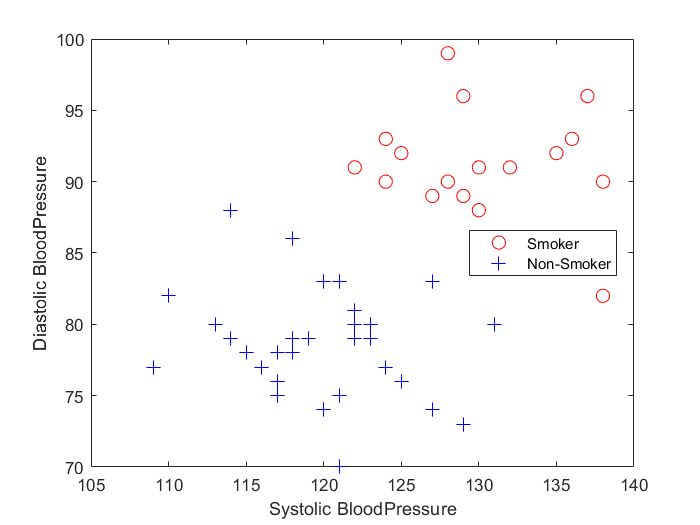

gscatter(data_train(:,1), data_train(:,2), label_train, 'rb', 'o+', 8, 'on')
xlabel('Systolic BloodPressure');
ylabel('Diastolic BloodPressure');
legend('Location', 'best');

# **CASO k = 1**

**Se realiza el entrenamiento del modelo.**

k = 1;
model_kNN = fitcknn(data_train, label_train, 'NumNeighbors', k);

**Visualizamos la matriz de confusión del modelo, que compara los valores verdaderos con las predicciones.**

label_prediction = predict(model_kNN, data_test);
confusion_mat = confusionmat(label_test, label_prediction);

confusion_mat =     12     5
     2    31


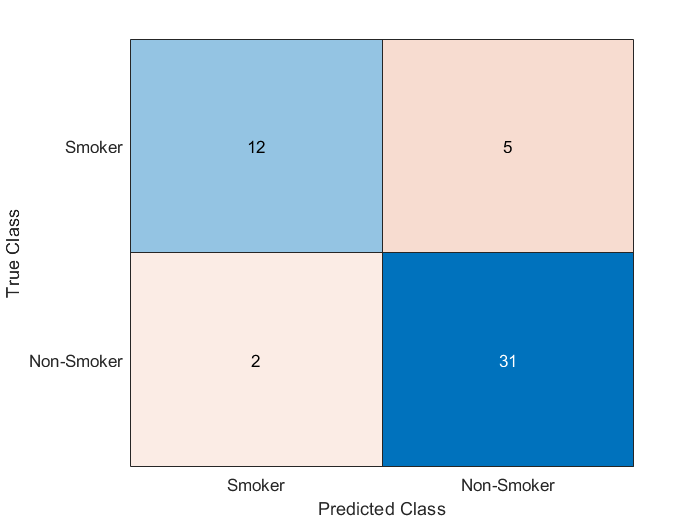

confusion_chart = confusionchart(label_test, label_prediction);

**En la siguiente tabla, indicamos qué es cada uno de los valores de la tabla.**

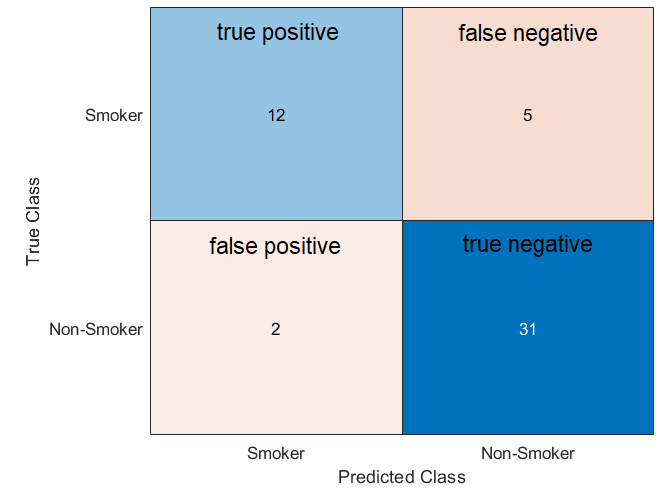

 % especificidad = TN/(TN+FP)
 % sensibilidad = TP/(TP+FN)